(1) Moments

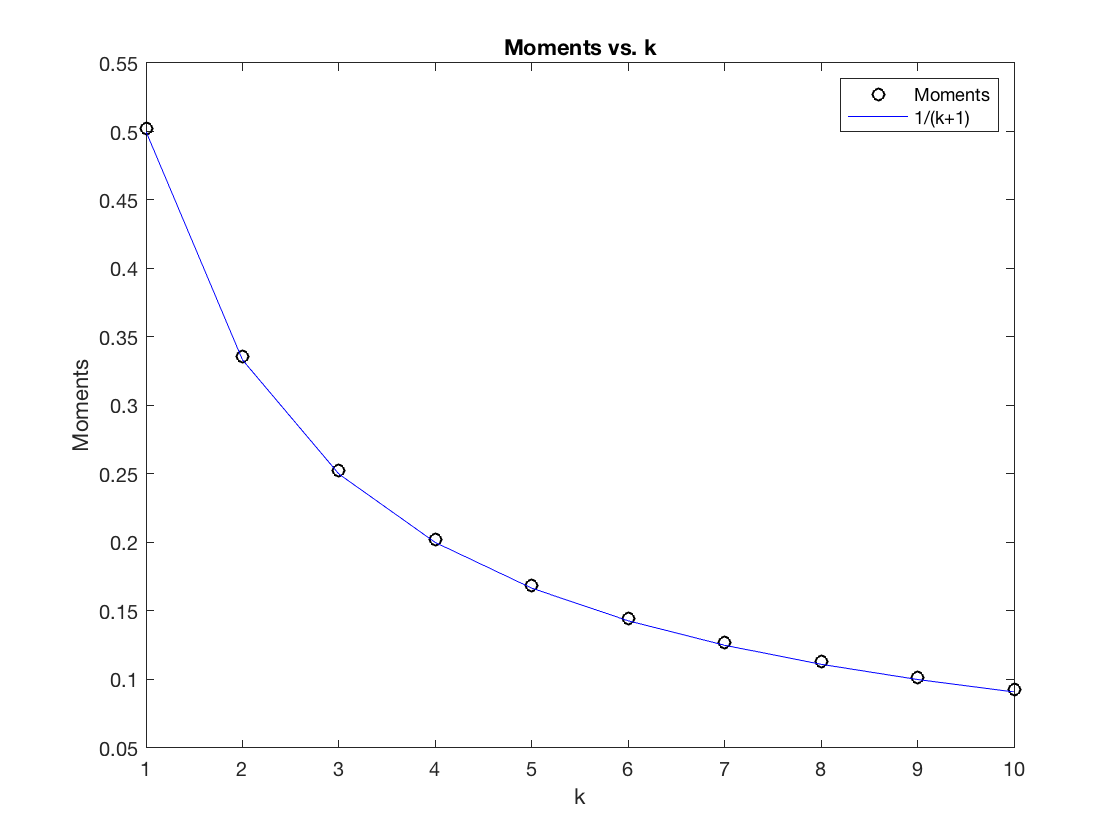

clc
clear all
N=50000;
a=65539;
M=2^31;
r=lcg(a,M,N);
mo=0;
k=[1:10];
for i=1:length(k)
    for j=1:N
        mo=mo+r(j).^i;
    end
    m(i)=mo;
    mo=0;
end
m=m./N;
plot(k,m,'ko',k,1./(k+1),'b-')
xlabel('k')
ylabel('Moments')
title('Moments vs. k')
legend('Moments','1/(k+1)')

a=65539;
M=2^31;
NN=linspace(5,4000,30);%check deviation
var=0;
mo=0;
for l=1:length(NN)
    r=lcg(a,M,NN(l));
    for i=1:length(k)
         for j=1:NN(l)
             mo=mo+r(j).^i;
         end
         mo=mo/NN(l);
         var=var+(mo-(1/(i+1)))^2; %calculating the varation (absolute value)
         mo=0;
    end
    v(l)= sqrt(var/length(k)); %calculating the average varation 
    var = 0;
end 
funfit=@(x,NN) x(1)*NN.^(-0.5)+x(2);
x0=[1,0];
x = lsqcurvefit(funfit,x0,NN,v);


Local minimum found.

Optimization completed because the size of the gradient is less than
the default value of the optimality tolerance.

<stopping criteria details>



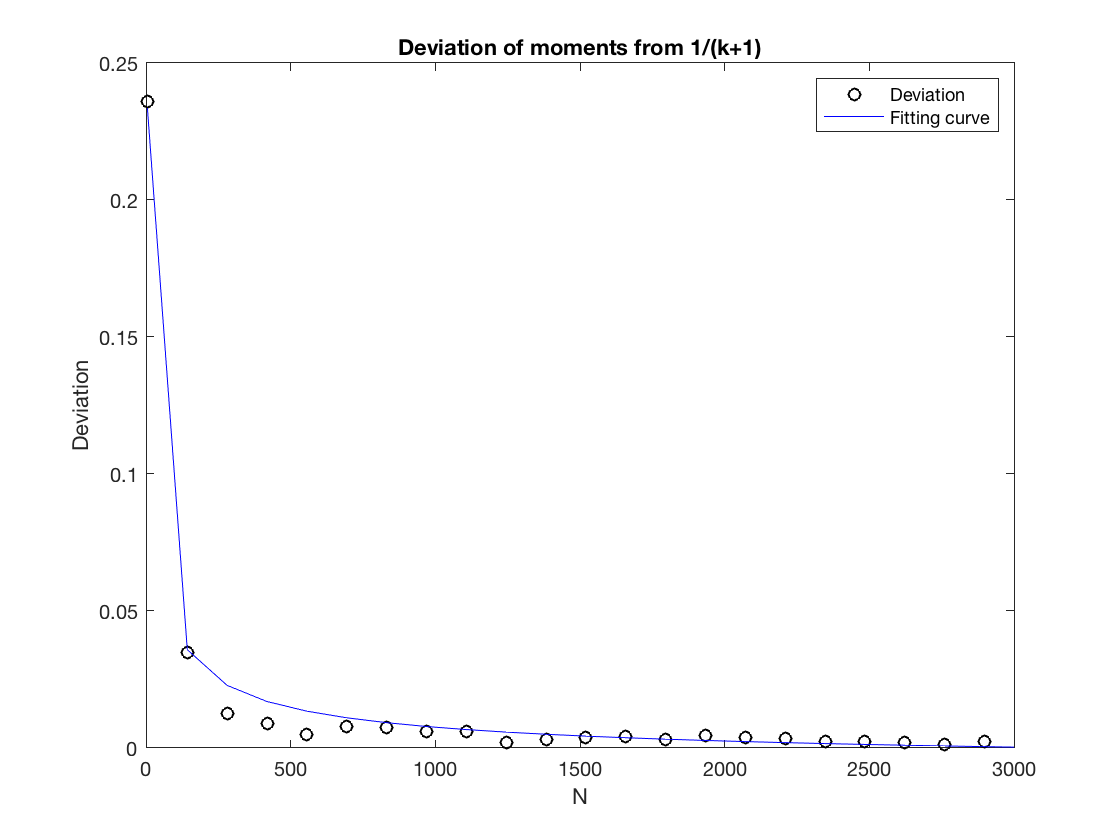

fitdata = x(1)*NN.^(-0.5)+x(2);
plot(NN,v,'ko',NN,fitdata,'b-')
legend('Deviation','Fitting curve')
xlabel('N')
ylabel('Deviation')
title('Deviation of moments from 1/(k+1)')
axis([0,3000,0,0.25])

Graph 1 showed us that moments varies as 1/(k+1) when N is very big. Graph 2 showed us the devition varies as 1/sqrt(N) and both results showed us that this generator is quite good. 

(2) Autocorrelation

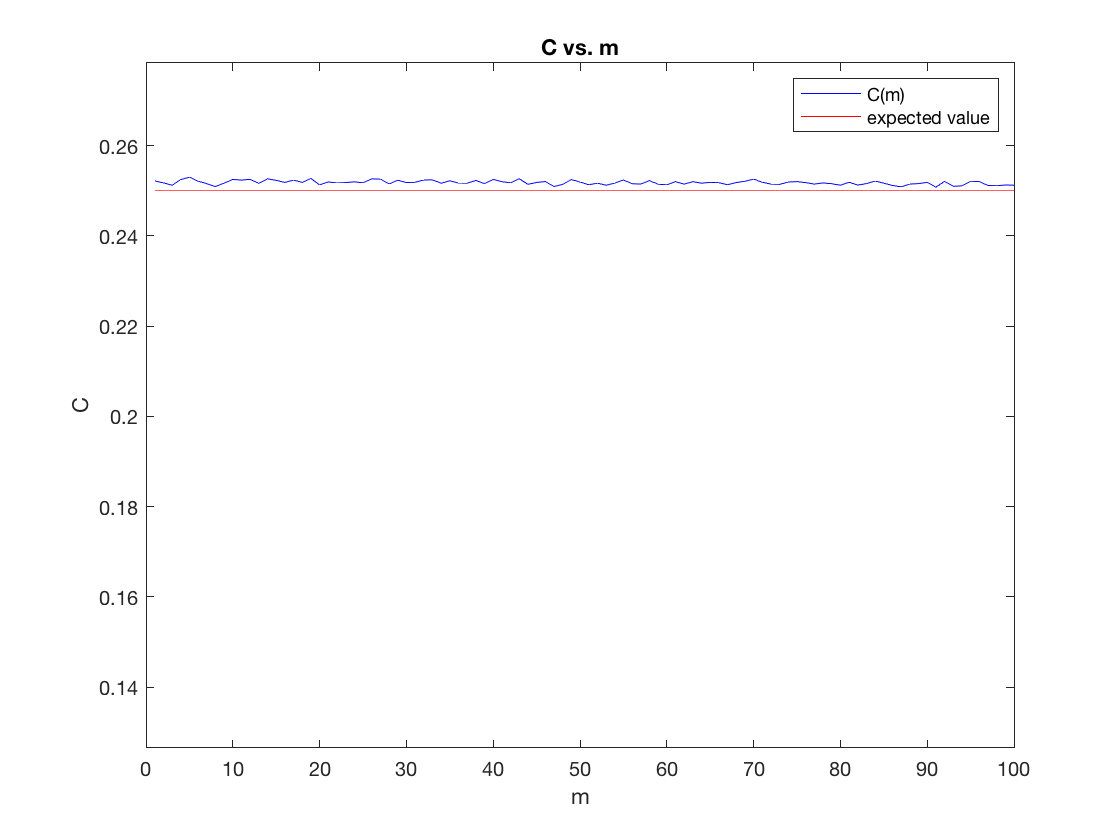

N=50000;
a=65539;
M=2^31;
r=lcg(a,M,N);
m=[1:100];
CC=0;
for i=1:length(m)
    for j=1:N-m(i)
        CC=CC+r(j)*r(j+m(i));
    end
    C(i)=CC/N;
    CC=0;
end
plot(m,C,'b',m,ones(length(m))*0.25,'r')
axis([0,length(m),0.5*max(C),1.1*max(C)])
title('C vs. m')
xlabel('m')
ylabel('C')
legend('C(m)','expected value')

Given that the analytic solution is 0.25, this generator seems good.

(3) Visual test 

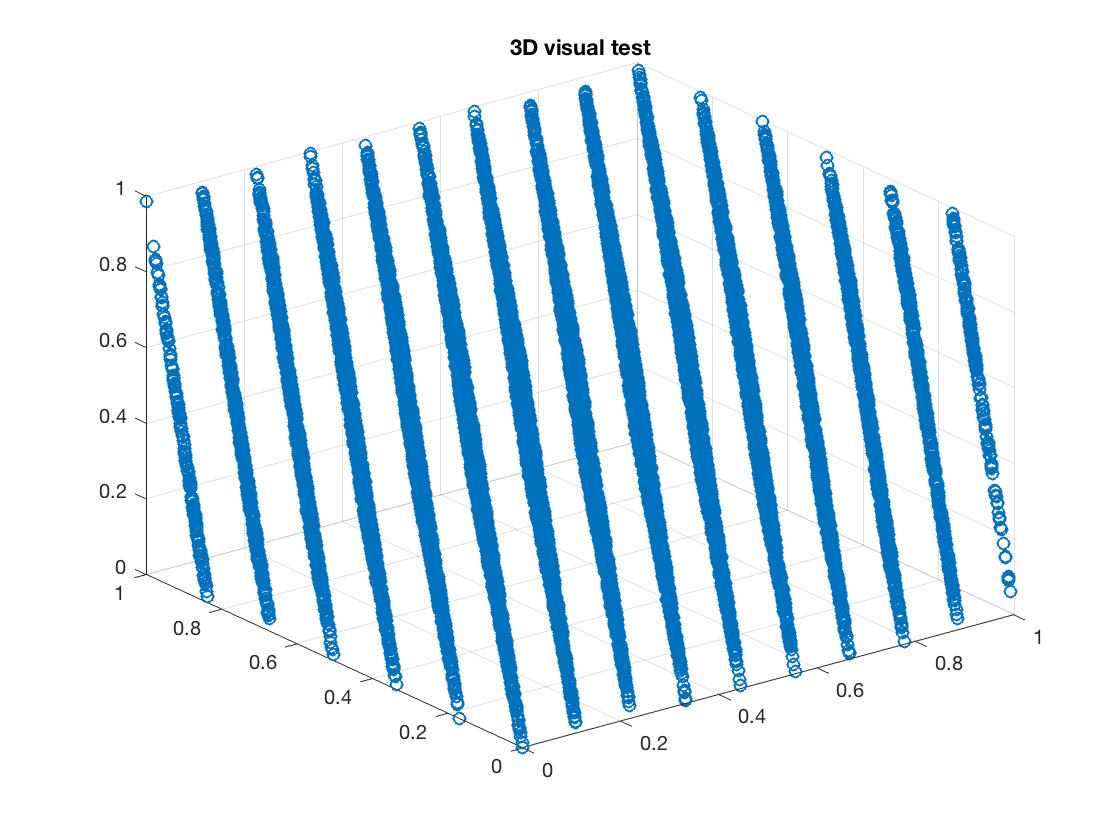

N=60000;
a=65539;
M=2^31;
r=lcg(a,M,N);
for i=1:N/3
    r1(i)=r(3*i-2);
    r2(i)=r(3*i-1);
    r3(i)=r(3*i);
end
scatter3(r1,r2,r3)
title('3D visual test')

This generator fails in the 3D visual test.